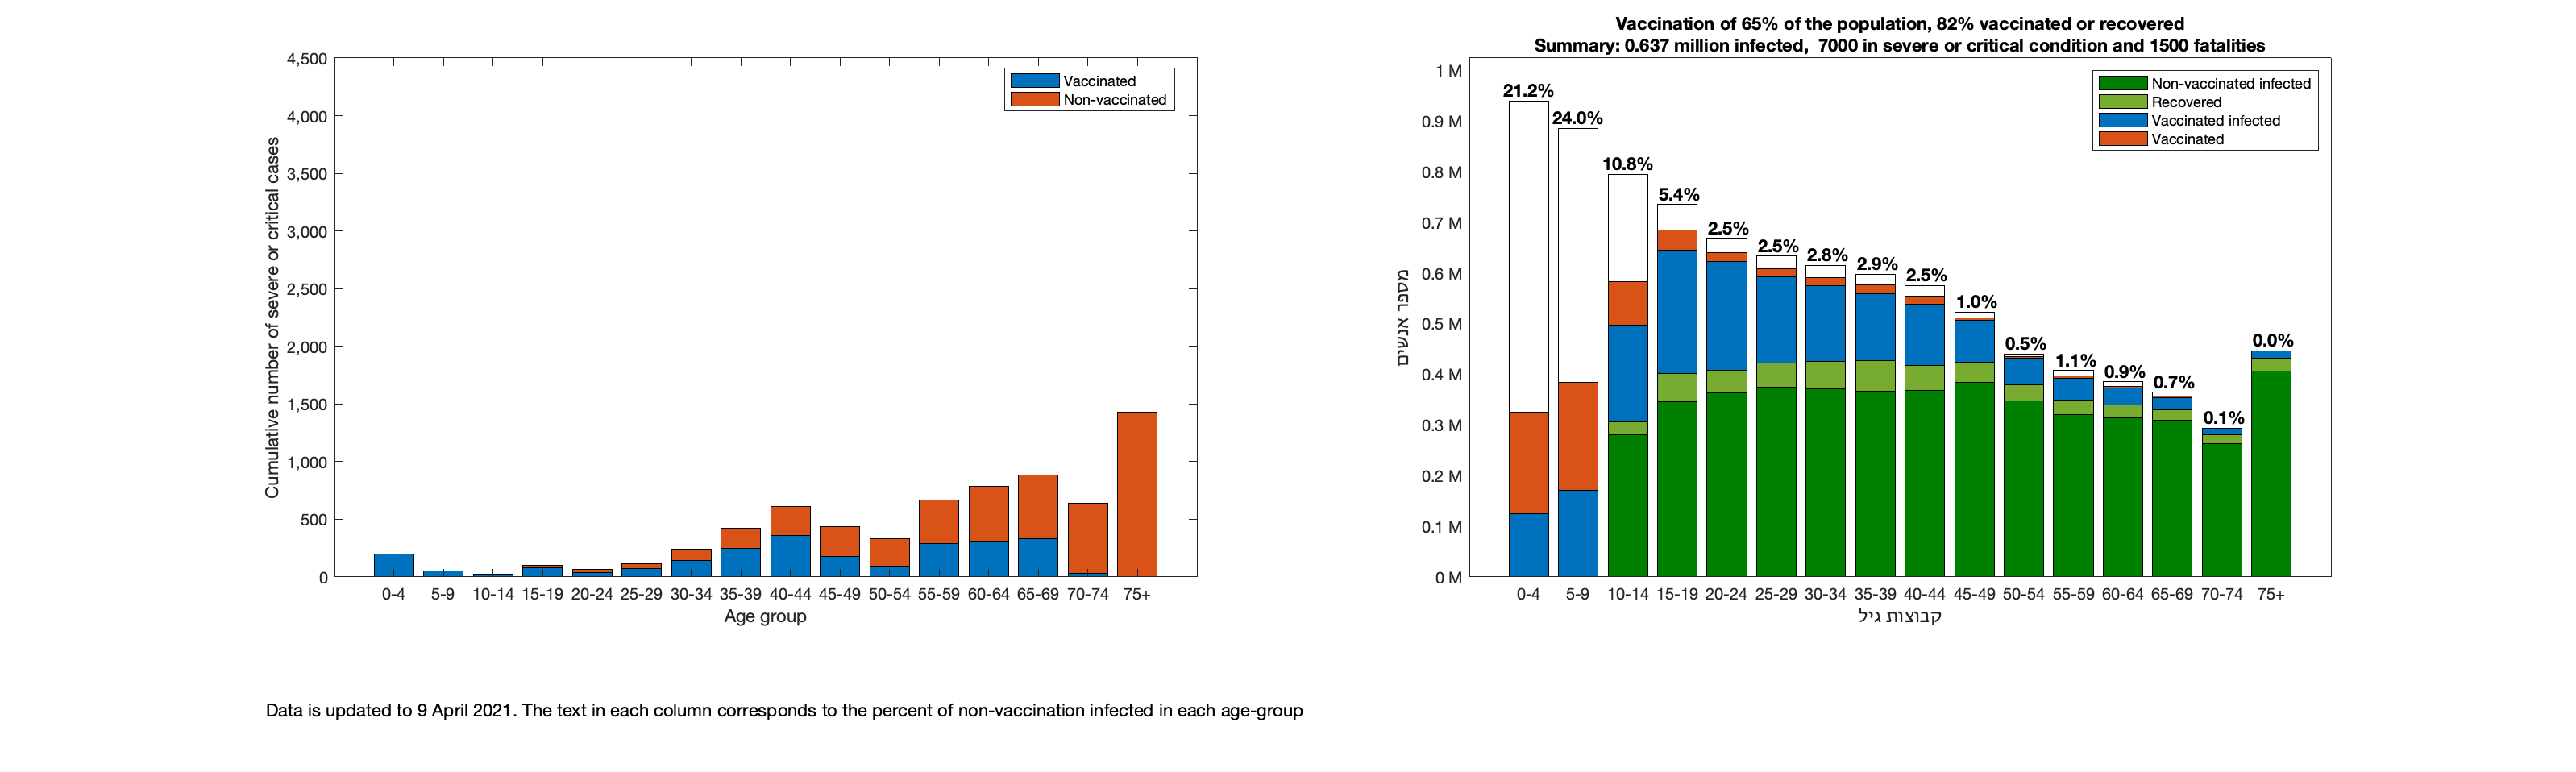


R0=3.5;VE_infections=75;VE=95;i0=0;
betaVac=1-VE_infections/100;
effVac=1-(1-VE/100)/betaVac;
%betaVac=0;nuVac=0.8;
overallVeff=1-betaVac*(1-effVac);

% Contact matrix
useCovidMatrix=true;nuVac=1;
close all
load IsraelContactMatrices.mat
if useCovidMatrix
    contactMatrix=CovidCij;
else
    contactMatrix=preCovidCij;
end

Ni=[0.1010 0.0952 0.0854 0.0790 0.0718 0.0681 0.0661 0.0642 0.0618 0.0562 0.0473 0.0438 0.0414 0.0392 0.0316 0.0480]'*9.3e6;


susVec=[0.5 0.5 0.5 ones(1,13)];
infVec=[0.75 0.75 0.75 ones(1,13)];
contactMatrix=diag(susVec)*contactMatrix*diag(infVec);
Mij=diag(Ni)*contactMatrix*diag(1./Ni);
[V,d]=eig(Mij);contactMatrix=contactMatrix/max(d(:));

% Prepare data
Cij=contactMatrix;
detRates=[0.4*ones(1,9),0.55,0.70,0.70,0.70,0.70,0.85,1]';
%detRates=[0.2*ones(1,9),0.55,0.70,0.70,0.70,0.70,0.85,1]';
IFR=[0,0,0,0,0,0,0,0,0,0.001,0.003,0.006,0.012,0.024,0.049,0.164]'./detRates;
ISR=[0.0004,0.0001,0.0001,0.0008,0.0010,0.0018,0.0034,0.0057,0.0100,0.0180,0.0269,0.0462,0.0649,0.0926,0.1529,0.2898]'./detRates;

adultAges=3:16;
Nadult=Ni(adultAges);
ix=1;
% Infected/recovered/vaccinated
rKnown=[49967 68429 76767 97743 85793 67837 59189 52699 48466 45101 36691 29868 23161 17106 11127 15491]'./Ni;
r=rKnown./detRates;
runKnown=r-rKnown;
v_wasted=runKnown./(1-rKnown);
v=[320    156    350 326475 493972 451939 446919 445365 433317 437108 384319 341760 333801 322872 295377 448257]'./Ni;
v_actual=(1-v_wasted).*v;
infected0_nv=i0*[0.045, 0.062, 0.079 ,0.127, 0.112 ,0.086 ,0.074, 0.067, 0.065, 0.063 ,0.053, 0.045 ,0.037, 0.029 ,0 ,0.035]'./Ni;
infected0_v=0*[0, 0, 0 ,0.127, 0.112 ,0.086 ,0.074, 0.067, 0.065, 0.063 ,0.053, 0.045 ,0.037, 0.029 ,0 ,0.035]'./Ni;

s=1-r-v-infected0_v-infected0_nv;
v=1-max(0,s)-infected0_v-infected0_nv-r;v_actual=(1-v_wasted).*v;
s=max(0,1-r-v-infected0_v-infected0_nv);
Ni50plusfilter=ones(16,1);Ni50plusfilter(1:10)=0;
Ni1649filter=zeros(16,1);Ni1649filter(1:3)=0;Ni1649filter(4)=0.8;Ni1649filter(5:10)=1;
Ni1215filter=zeros(16,1);Ni1215filter([1 2 5:16])=0;Ni1215filter(3)=0.6;Ni1215filter(4)=0.2;
Ni50plus=Ni.*Ni50plusfilter;
Ni1649=Ni.*Ni1649filter;
Ni1215=Ni.*Ni1215filter;

% Additional vaccine for 50+
sVacc=max(1-rKnown-v-infected0_v-infected0_nv,0);
maxadditional50=round(0.95*sum(sVacc.*Ni50plus));

% Additional vaccine for 16+
maxadditional16=round(0.95*sum(sVacc.*Ni1649));

% Additional vaccine for 12-15
maxadditional1215=round(0.95*sum(sVacc.*Ni1215));

additional16=460000;additional50=60000;additional1215=420000;

% Additional parameters
useCovidMatrix=true;

% Vaccine distribution
% v_protected=infected+r-1;
vaccineDistribution=zeros(16,1);
vaccineDistribution=additional1215*Ni1215filter.*sVacc/sum(Ni1215filter.*sVacc)+additional16*sVacc.*Ni1649/sum(sVacc.*Ni1649)+additional50*sVacc.*Ni50plus/sum(sVacc.*Ni50plus);
vaccineDistribution=(1-v_wasted).*vaccineDistribution./Ni;
vaccineDistribution=vaccineDistribution(adultAges);
% Compute uniform allocation of vaccines
%vaccinesLeftToDistibute=Vc-sum(v);
%upperBound=max(s(adultAges)-(1-maxPrct/100),0);
%uniformAllocation=computeUniformAllocation(s,adultAges,Nadult,vaccinesLeftToDistibute,upperBound);
    
[result,overallInfected,overallMortality,overallSevere,data]=computeFinalSizeIsrael(vaccineDistribution,adultAges,IFR,ISR,0,R0,Cij,Ni,r,v_actual,infected0_v,infected0_nv,nuVac,betaVac,effVac,1,1);

subplot(6,2,2:2:10);presentData(data,Ni,overallMortality)
%sum(([0;0;vaccineDistribution]+v).*Ni)/sum(Ni)
% titleTextScenario=['גודל מגפה סופי עבור R=',num2str(R0)];
titleTextScenario=['Vaccination of ',num2str(sum(([0;0;vaccineDistribution]./(1-v_wasted)+v).*Ni)/sum(Ni)*100,2),'% of the population'];
titleTextScenario2=[num2str(sum(([0;0;vaccineDistribution]+r+v).*Ni)/sum(Ni)*100,2),'% vaccinated or recovered'];
titleTextSummarya=['Summary: ',num2str(overallInfected/1e6,3),' million infected, '];
titleTextSummaryb=[num2str(round(overallSevere,-2)),' in severe or critical condition'];
titleTextSummaryc=['and ',num2str(round(overallMortality,-2)),' fatalities'];
titleTextSummary=[titleTextSummarya,' ',titleTextSummaryb,' ',titleTextSummaryc];
title({[titleTextScenario,', ',titleTextScenario2],titleTextSummary});

% linkaxes([axVec{1} axVec{2} axVec{3}],'xy');
% xlim(axVec{1},[0.5 9.5])
% lg = legend(axVec{3},'Vaccinated susceptible','Vaccinated infected','Recovered','Non-vaccinated infected','location','northeast','fontsize',10);%,'Orientation','horizontal');%legend(nexttile(2), [line1,line2,line3,line4]);
% axVec{1}.Children(13)
% lg = legend([axVec{1}.Children(15) axVec{1}.Children(14) axVec{1}.Children(12)],'Vaccinated susceptible','Vaccinated infected','Non-vaccinated infected','location','northeast','fontsize',10);%,'Orientation','horizontal');%legend(nexttile(2), [line1,line2,line3,line4]);
% lg = legend([axVec{2}.Children(15) axVec{1}.Children(14) axVec{1}.Children(12)],'Vaccinated susceptible','Vaccinated infected','Non-vaccinated infected','location','northeast','fontsize',10);%,'Orientation','horizontal');%legend(nexttile(2), [line1,line2,line3,line4]);
% ylim(axVec{3},[0 50.1])
% % lg.Lylim([0 53])
% text(axVec{1},0.02,0.92,'A','units','normalized','fontsize',11)
% text(axVec{2},0.02,0.92,'B','units','normalized','fontsize',11)
% text(axVec{3},0.02,0.92,'C','units','normalized','fontsize',11)
set(gcf,'Position',[1 1 2000 600]);
remark_date='Data is updated to 9 April 2021';
remark1='The text in each column corresponds to the percent of non-vaccination infected in each age-group';
annotation('textbox', [0.1, 0.1, 0.8, 0], 'string',{[remark_date,'. ',remark1]},'HorizontalAlignment', 'left','fontsize',11)
% legend('מחוסנים','נדבקים מחוסנים','מחלימים','נדבקים לא מחוסנים','location','northeast');
legend('Non-vaccinated infected','Recovered','Vaccinated infected','Vaccinated','location','northeast');
%return
%printGraph(['R0=3,8,Leaky,Scenario',num2str(ix)]);close all;
subplot(6,2,1:2:9);infected_v=data(:,2);
infected_nv=data(:,4);
overallSevere_v=((0*infected_nv+nuVac*(1-effVac)*infected_v+(1-nuVac)*infected_v)).*ISR; % Overall number of deaths
overallSevere_nv=((infected_nv+0*nuVac*(1-effVac)*0*infected_v+(1-nuVac)*infected_v)).*ISR; % Overall number of deaths

bar([overallSevere_nv overallSevere_v],'stacked')
ax = gca;ax.YRuler.Exponent = 0;ytickformat('%,2.0f')
agDistLabels={'0-4','5-9','10-14','15-19','20-24','25-29','30-34','35-39','40-44','45-49','50-54','55-59','60-64','65-69','70-74','75+'};
xlabel('Age group');ylabel('Cumulative number of severe or critical cases');
legend('Vaccinated','Non-vaccinated','location','best')

set(gca,'xtick',1:numel(agDistLabels),'xticklabel',agDistLabels);ylim([0 4500])

%printGraph(['R0=3,8,Leaky,Sevr,Scenario',num2str(ix)]);close all;

% remark_date='הנתונים מעודכנים לתאריך 10.3.2021';
% remark1='הטקסט בכל עמודה מתייחס לאחוז הנדבקים הלא מחוסנים בכל קבוצת גיל.';
% remark_names='פרופ׳ ניר גביש, ד״ר עמית הופרט, ד״ר רמי יערי, פרופ׳ חגי כתריאל';
% annotation('textbox', [0.1, 0.1, 0.8, 0], 'string',{[remark_date,'. ',remark1],remark_names},'HorizontalAlignment', 'right','fontsize',11)
%set(gcf,'Position',[520 354 867 443]);ylim([0 5000])

function presentData(data,N,overallFatality)
% subplot(6,6,[1:5 7:12 13:18 19:24]);
%data=[sus_v.*N infected_v.*N r.*N infected_nv.*N sus_nv.*N];data=[data N-sum(data,2)];
sus_v=data(:,1);
infected_v=data(:,2);
r=data(:,3);
infected_nv=data(:,4);
sus_nv=data(:,5);
green=[0.4660 0.6740 0.1880];red=[0.8500 0.3250 0.0980];
darkgreen=[0 0.5 0];
blue=[0 0.4470 0.7410];
h=bar(data/1e6,'stacked');
h(1).FaceColor=darkgreen;h(2).FaceColor=green;h(3).FaceColor=blue;h(3).FaceColor=blue;h(4).FaceColor=red;h(5).FaceColor='w';
hT=[];
ix=4;
yCoord=N-sus_nv;
idx=find(infected_nv<0.22e7);
yCoord(idx)=N(idx);
noidx=find(infected_nv>0.22e7);
%yCoord(end-1:end)=N(end-1:end);

text(h(ix).XData(noidx)+h(ix).XOffset,yCoord(noidx)/1e6,num2str(100*infected_nv(noidx)./N(noidx),'%2.1f%%'), ...
    'VerticalAlignment','top','horizontalalign','center','fontsize',11,'color','w','fontweight','bold');

text(h(ix).XData(idx)+h(ix).XOffset,yCoord(idx)/1e6,num2str(100*infected_nv(idx)./N(idx),'%2.1f%%'), ...
    'VerticalAlignment','bottom','horizontalalign','center','fontsize',11,'color','k','fontweight','bold');

% for ix=1:numel(idx);hT(idx(ix)).Color='k';end%hT(end-1).Color='k';
ax = gca;ax.YRuler.Exponent = 0;ytickformat('%,2.2f M')
agDistLabels={'0-4','5-9','10-14','15-19','20-24','25-29','30-34','35-39','40-44','45-49','50-54','55-59','60-64','65-69','70-74','75+'};
xlabel('קבוצות גיל')


set(gca,'xtick',1:numel(agDistLabels),'xticklabel',agDistLabels);
% legend('Vaccinated susceptible','Vaccinated infected','Recovered','Non-vaccinated infected','location','northeast','fontsize',11);
ax = gca;ax.YRuler.Exponent = 0;

%if max(N)>1e6
%    ylim([0 1.05*max(N)]);ytickformat('%,8.0f M')
%else
    ylim([0 1.09*max(N)]/1e6);ytickformat('%,4.0g M')
%end

%     annotation('textbox', [0.1, 0.1, 0.8, 0], 'string', {'The number above each bar is the percent of non-vaccinated individuals which will be infected','Prof. Nir Gavish, Dr. Amit Huppret, Prof. Guy Katriel, Dr. Rami Yaari'},'fontsize',12)
ylabel('מספר אנשים');
jf=java.text.DecimalFormat;
set(gca,'TickLength',[0 0])

%titleText=['Additional ',num2str(sum(infected_nv)/1e6,3),'M non-vaccinated individuals infected and additional fatality of ',char(jf.format(round(overallFatality,-2))),' people'];
%title(titleText,'FontSize',12);

end

function y = g(z,A,r,v,infected,betaVac)
s=1-r-v-infected;
s_inf_normalized=exp(-A*(z-r./s));
v_inf_normalized=v./s.*s_inf_normalized.^betaVac;
y=1./s-z-s_inf_normalized-v_inf_normalized;
end